# Sistema de monitoreo en cuarto de temperatura

Código: 203036_111

Rubén De La Puente 

% Inicializamos la matriz 3x3 (3 zonas x 3 momentos al día)

clc, clear

zonas = 3;
momentos = 3; 
temperatura = zeros(zonas, momentos);

% Ingreso de datos 

for i = 1:zonas
    for j = 1:momentos
        prompt = sprintf("Ingrese la temperatura de la zona %d, en el momento %d (°C): ", i, j);
        temperatura(i,j) = input(prompt);
    end
end

% Verificación de temperaturas superiores a 40°C 

for i = 1:zonas
    for j = 1:momentos
        if temperatura (i,j) > 40
            switch j
                case 1 
                    momento = 'Mañana';
                case 2 
                    momento = 'Tarde';
                case 3 
                    momento = 'Noche';
            end
            fprintf("⚠️ Alerta: Zona %d supera los 40°C en la %s (%.1f°C)\n", i, momento, temperatura(i,j));
        end
    end
end

⚠️ Alerat: Zona 1 supera los 40°C en la Noche (45.0°C)



fprintf("Verificación completada..!");

Verificación completada..!

% --- SECCIÓN DE GRÁFICA ---
disp('--- Generando Gráfica ---');

--- Generando Gráfica ---


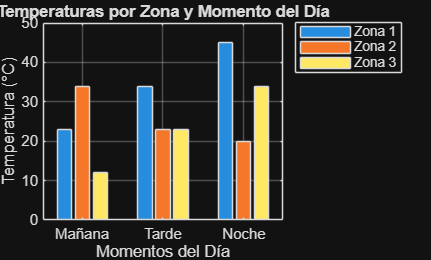


% Crear una nueva figura para la gráfica
figure; 

% Graficar los datos usando barras
bar(temperatura'); % Se usa la transpuesta para agrupar por momentos

% Configuraciones de la gráfica
title('Temperaturas por Zona y Momento del Día');
xlabel('Momentos del Día');
ylabel('Temperatura (°C)');

% Personalizar las etiquetas del eje X
set(gca, 'XTickLabel', {'Mañana', 'Tarde', 'Noche'});

% Agregar una leyenda para identificar cada zona
legend('Zona 1', 'Zona 2', 'Zona 3', 'Location', 'northeastoutside');

% Agregar una cuadrícula para mejor lectura
grid on;


fprintf("Gráfica generada exitosamente.\n");

Gráfica generada exitosamente.
